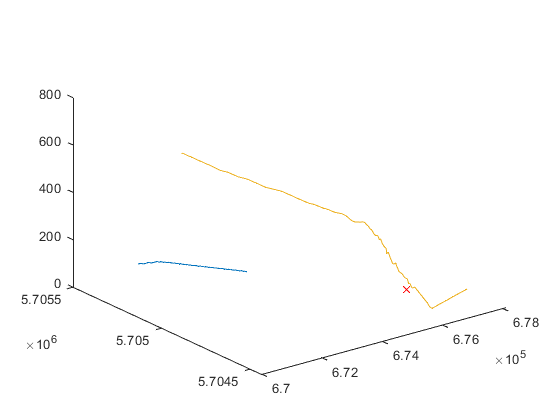

clear
clc

drone_data = importdata("Drone_coords.txt");
aircraft_data = importdata("TAKEOFF_UTM_DEPART_A320 LHR time - 2017-06-30 04-00 to 2017-06-30 23-45.csv");

aircraft_index = [2];

callsign = string(aircraft_data.textdata(:,4));
longitude = str2double(string(aircraft_data.textdata(:,15)));
latitude = str2double(string(aircraft_data.textdata(:,14)));
altitude = str2double(string(aircraft_data.textdata(:,8)));

for i = 2:length(callsign)+1
    if i == length(callsign)
        aircraft_index(end+1) = i+1;
        break
    end
    if callsign(i) ~= callsign(i+1)
        aircraft_index(end+1) = i+1;
    end
    
end

index_select = 1;


figure
plot3(drone_data(1:end-1,1),drone_data(1:end-1,2),drone_data(1:end-1,3))
hold on
plot3(drone_data(end,1),drone_data(end,2),drone_data(end,3),'xr')
plot3(longitude(aircraft_index(index_select):aircraft_index(index_select+1)-1), latitude(aircraft_index(index_select):aircraft_index(index_select+1)-1), altitude(aircraft_index(index_select):aircraft_index(index_select+1)-1))